datapath = ...
    {"/Volumes/yaochen/Active/Pingchuan/2023Fall/laser_power_slice_20X/20230814_AChSensor_Slice_002_LaserPower_20X/",...
    "/Volumes/yaochen/Active/Pingchuan/2023Fall/laser_power_slice_20X/20230814_AChSensor_Slice_003_LaserPower_20X",...
    "/Volumes/yaochen/Active/Pingchuan/2023Fall/laser_power_slice_20X/20230815_AChSensor_Slice_003_LaserPower_20X/",...
    "/Volumes/yaochen/Active/Pingchuan/2023Fall/laser_power_slice_20X/20230816_AChSensor_Slice_002_LaserPower_20X/",...
    "/Volumes/yaochen/Active/Pingchuan/2023Fall/laser_power_slice_20X/20230816_AChSensor_Slice_004_LaserPower_20X/",...
    "/Volumes/yaochen/Active/Pingchuan/2023Fall/laser_power_slice_20X/20230817_AChSensor_Slice_002_LaserPower_20X",...
    "/Volumes/yaochen/Active/Pingchuan/2023Fall/laser_power_slice_20X/20230817_AChSensor_Slice_004_LaserPower_20X"...
    }

stateYao_file = ...
    {"Analysis_offset0_20230918.mat",...
    "Analysis_offset0_20230918.mat",...
    "Analysis_offset0_20230918.mat",...
    "Analysis_offset0_20230918.mat",...
    "Analysis_offset0_20230918.mat",...
    "Analysis_offset0_20230918.mat",...
    "Analysis_offset0_20230918.mat",...
    }

all_epochs_all = ...
    {[2 3 4],...
    [2 3 4],...
    [2 3 4],...
    [2 3 4],...
    [2 3 4],...
    [2 3 4],...
    [2 3 4],...
    }; % all the epochs

drug_epochs_all = ...
    {[2 3 4],...
    [2 3 4],...
    [2 3 4],...
    [2 3 4],...
    [2 3 4],...
    [2 3 4],...
    [2 3 4],...
    }; % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

summary_files = {};
summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/ACh_sensor_slice/laser_power_slice_20X/'

CyclePositions = [1 2]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation
FigureVisible = 'on'

for i =1:7
    cd(datapath{i});
    load(stateYao_file{i});

    all_epochs = all_epochs_all{i};
    drug_epochs = drug_epochs_all{i};

    mask = zeros(128,128) +1;
    for j = 1:length(CyclePositions)

        ROI_mask = calc_NonDeadTimeMask(stateYao.images.origData.projects{j});
        mask(find(ROI_mask == 0)) = 0;
    end

    figure
    heatmap(mask)
    grid off
    Ax = gca;
    Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
    Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
    saveas(gcf, [summary_path, stateYao.baseName,'_', '_mask.png'])

    for k = 1:length(CyclePositions)

        [lifetime_wholeFOV, intensity_wholeFOV] = calc_intensity_lifetime_wholeFOV(stateYao.images.origData.projects{k}, stateYao.images.origData.lifetimeMaps{k}, mask);
    
        stateYao.Results.spc_calculateROIvals.Projection{k} = intensity_wholeFOV;
        stateYao.Results.spc_calculateROIvals.LifetimeMap{k} = lifetime_wholeFOV;
    end
    
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode(CyclePositions);
    % [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all);
    
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all, FigureVisible, summary_path)
    currTime = datestr(datetime('now'));
    currTime = currTime(1:11);
    summary_files{i} = [stateYao.baseName,'_',currTime, '_1_2.mat'];


end

cd(summary_path)
save('summary_files.mat', 'summary_files')

cd(summary_path)
load('summary_files.mat')
valid_recordings = [1 2 4 5 6 7];

lifetime_all_high = [];
lifetime_all_low = [];
intensity_all_high = [];
intensity_all_low = [];

lifetime_response_all_high = [];
lifetime_response_all_low = [];
intensity_response_all_high = [];
intensity_response_all_low = [];

for i = valid_recordings

    load(summary_files{i})
    lifetime_all_high = [lifetime_all_high epoch_response_lft_all{1}];
    lifetime_all_low = [lifetime_all_low epoch_response_lft_all{2}];

    intensity_all_high = [intensity_all_high epoch_response_intensity_all{1}];
    intensity_all_low = [intensity_all_low epoch_response_intensity_all{2}];


    lifetime_response_all_high = [lifetime_response_all_high epoch_response_lft_norm_all{1}];
    lifetime_response_all_low = [lifetime_response_all_low epoch_response_lft_norm_all{2}];

    intensity_response_all_high = [intensity_response_all_high epoch_response_intensity_norm_all{1}];
    intensity_response_all_low = [intensity_response_all_low epoch_response_intensity_norm_all{2}];



end

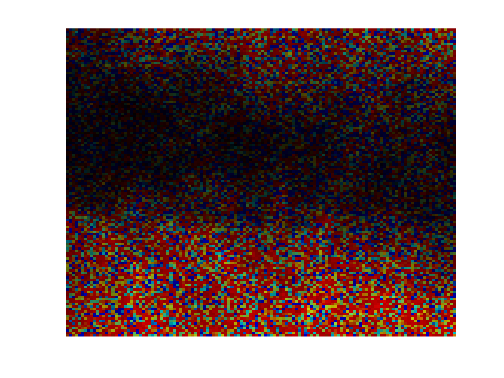

chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;


figure
h=heatmap(spc.projects{1});
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


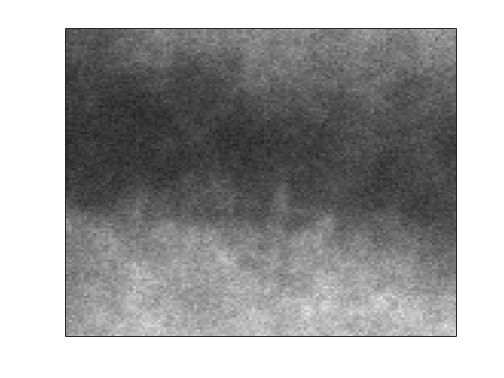

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 300];

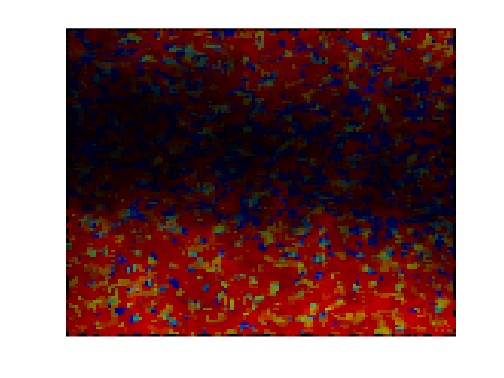

chan=1;

figure
rgbLifetimes_filterd = spc.rgbLifetimes{chan};
rgbLifetimes_filterd(:,:,1) = medfilt2(spc.rgbLifetimes{chan}(:,:,1));
rgbLifetimes_filterd(:,:,2) = medfilt2(spc.rgbLifetimes{chan}(:,:,2));
rgbLifetimes_filterd(:,:,3) = medfilt2(spc.rgbLifetimes{chan}(:,:,3));

image(rgbLifetimes_filterd);
axis off;


figure
a = medfilt2(spc.projects{1});
h=heatmap(a);
h.Colormap=gray

h =   HeatmapChart with properties:

        XData: {128×1 cell}
        YData: {128×1 cell}
    ColorData: [128×128 double]

  Show all properties


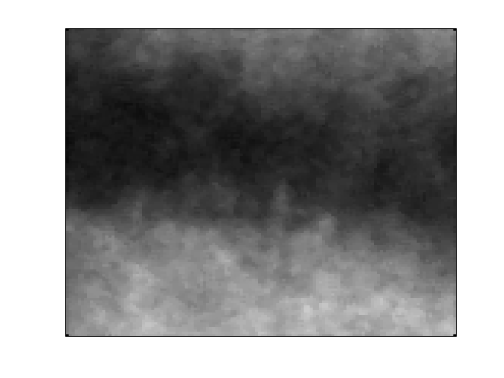

Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[40 300];

function [lifetime_values, intensity_values] = calc_intensity_lifetime_wholeFOV(projects, lifetimeMaps, mask)

num_acqs = size(projects, 3);

lifetime_values = {};
intensity_values = {};

for i = 1:num_acqs

    intensity_map = projects(:,:,i);
    lifetime_map = lifetimeMaps(:,:,i);

    lifetime_values{i,1} = Yao_calc_Lifetime(intensity_map, lifetime_map, mask);
    intensity_values{i,1} = Yao_calc_Projection(intensity_map, mask);

end

end


function mask = calc_NonDeadTimeMask(projects)

num_acqs = size(projects, 3);
mask = zeros(128,128) +1;

for i = 1:num_acqs
    intensity_map = projects(:,:,i);
    mask(find(intensity_map >= 300)) = 0;
end

end